pos_0 = [1, 0, 0];
vel_0 = [0, 1, 0];
v_quat_0 = compact(quaternion([0, 0, 45], 'eulerd', 'xyz', 'frame'));

v_states_0 = [pos_0(:); vel_0(:); v_quat_0(:)];
disp(v_states_0')

    1.0000         0         0         0    1.0000         0    0.9239         0         0    0.3827



states_0 = state_vec_to_struct(zeros(30, 1))

states_0 = struct with fields:
     posn_body: [3×1 double]
      vel_body: [3×1 double]
     quat_body: [1×1 quaternion]
        bias_f: [3×1 double]
    bias_omega: [3×1 double]
       posn_bv: [3×1 double]
       quat_vb: [1×1 quaternion]
      posn_tag: [3×1 double]
      quat_tag: [1×1 quaternion]


states_0.posn_body = [1, 0, 0];
states_0.vel_body = [0, 1, 0];
states_0.quat_body = quaternion([0, 0, 45], 'eulerd', 'xyz', 'frame');

states_0.quat_vb = quaternion([1, 0, 0, 0]);

states_0.quat_tag = quaternion([1, 0, 0, 0]);

v_states_0 = state_struct_to_vec(states_0);

f = [0, 0, 0];
omega = [0.4, 0, 0.2];

u = [f(:); omega(:)];
disp(u')

         0         0         0    0.4000         0    0.2000



% TODO FOR 3/17:
% 2) Configure testing to run multiple iterations

inputs = input_vec_to_struct(zeros(6, 1))

inputs = struct with fields:
        f: [3×1 double]
    omega: [3×1 double]


inputs.f = [0, 0, 0];
inputs.omega = [0.4, 0, 0.2];

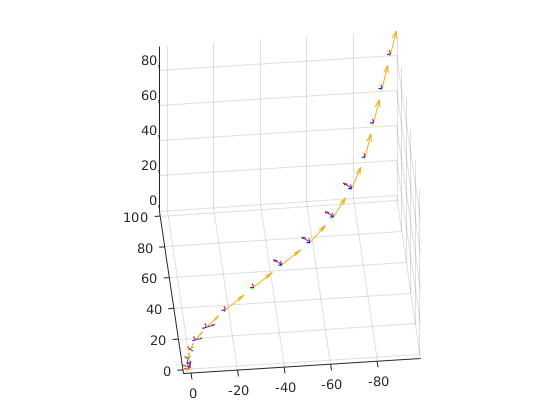

dt = 1.5; % seconds

iterations = 16;
mat_u = repelem(u, 1, iterations);
mat_u(3, 1:2) = 1;
mat_u(3, 4:7) = -1;
mat_u(4:6, 8:end) = repelem([0; 0; 0], 1, iterations - 8 + 1);
mat_u(1:3, 10:13) = repelem([sqrt(2); sqrt(2); 0], 1, 4);

[t_out, states_out] = sim_state_transition(v_states_0, mat_u, dt);
visualize(states_out, mat_u);

function fig = visualize(mat_states, mat_inputs)

% Check if we are missing the final inputs
if size(mat_inputs, 2) == size(mat_states, 2) - 1
    mat_inputs(1, end+1) = 0; % Create new blank column for inputs at final state
elseif size(mat_inputs, 2) ~= size(mat_states, 2)
    error("Input matrix size incompatible.")
end

mat_posns = mat_states(1:3, :)';
mat_vels = mat_states(4:6, :)';
mat_v_quats = mat_states(7:10, :)';
mat_quats = quaternion(mat_v_quats);

mat_forces = mat_inputs(1:3, :)';
mat_omegas = mat_inputs(4:6, :)';

% Body->World frame transformations
mat_vels_world_frame = rotatepoint(mat_quats, mat_vels);
mat_forces_world_frame = rotatepoint(mat_quats, mat_forces);

fig = figure();
clf;
hold on

plotTransforms(mat_posns, mat_quats, 'framesize', 1.8)
quiver3(mat_posns(:, 1), mat_posns(:, 2), mat_posns(:, 3), mat_vels_world_frame(:, 1), mat_vels_world_frame(:, 2), mat_vels_world_frame(:, 3), 'AutoScale','off')
quiver3(mat_posns(:, 1), mat_posns(:, 2), mat_posns(:, 3), mat_forces_world_frame(:, 1), mat_forces_world_frame(:, 2), mat_forces_world_frame(:, 3), 0.2)

grid on
axis equal

end